% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'
addpath './functions'

% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;   
N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

Benchmark model from Garnier Papanicolaou

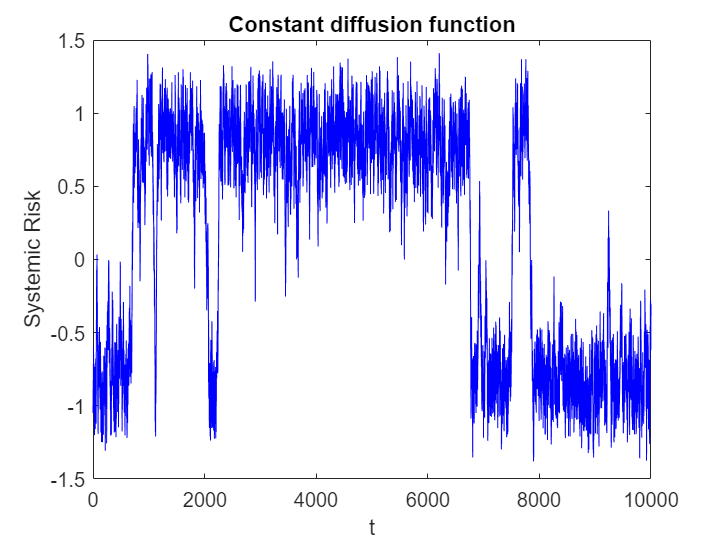

% Define SDE
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig;    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'yes');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant diffusion function")

Test that non-diagonal diffusion option works correctly (by setting D to be the diagonal matrix...)

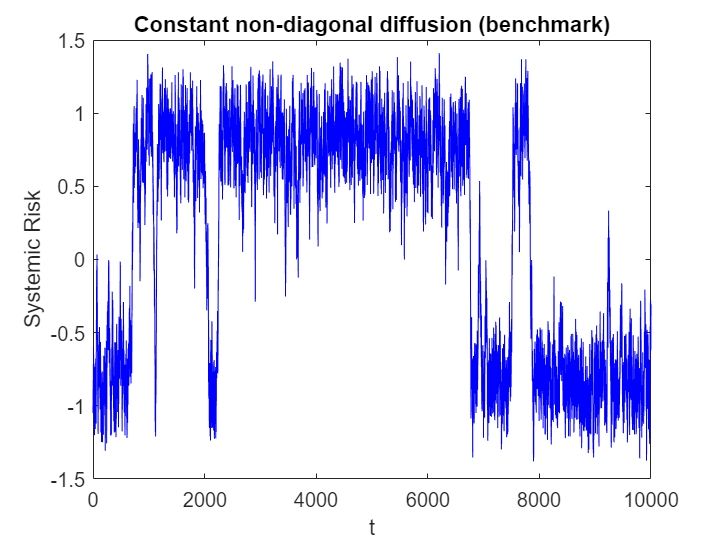

% Define SDE
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig.*eye(N);    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant non-diagonal diffusion (benchmark)")

Non-diagonal correlation matrix, given by:


$$\sigma * \left(\begin{array}{ccccc}
1 & 0.5 & 0 & \cdots & 0 \\
0.5 & 1 & 0.5 & \cdots & 0 \\
0 & 0.5 & 1 & \ddots & 0 \\
\vdots & \vdots & \ddots & \ddots & 0.5 \\
0 & 0 & \cdots & 0.5 & 1
\end{array}\right)$$


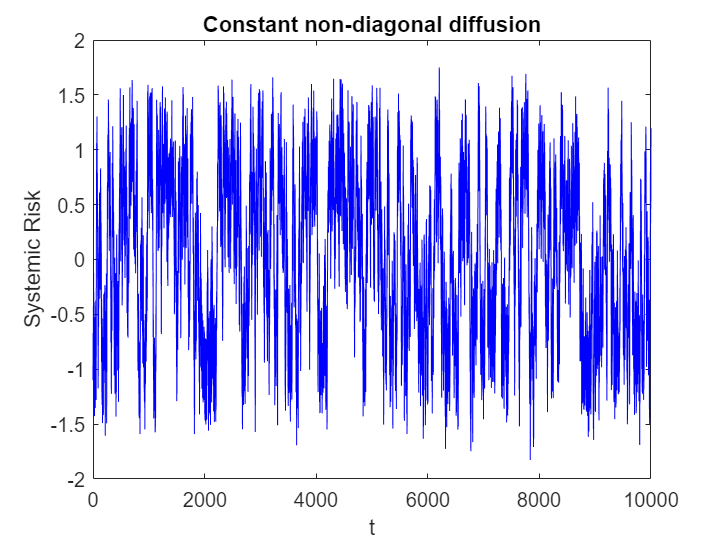

% Define SDE
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig.*(eye(N) + diag(0.5*ones(N-1, 1), 1) + diag(0.5*ones(N-1, 1), -1));    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant non-diagonal diffusion")

Adding correlation in the noise makes the system less stable.

Here I increase h from 0.1 to 0.5. Without correlated noise, increasing h increases the stability of the system. Here the effect is less pertinent.

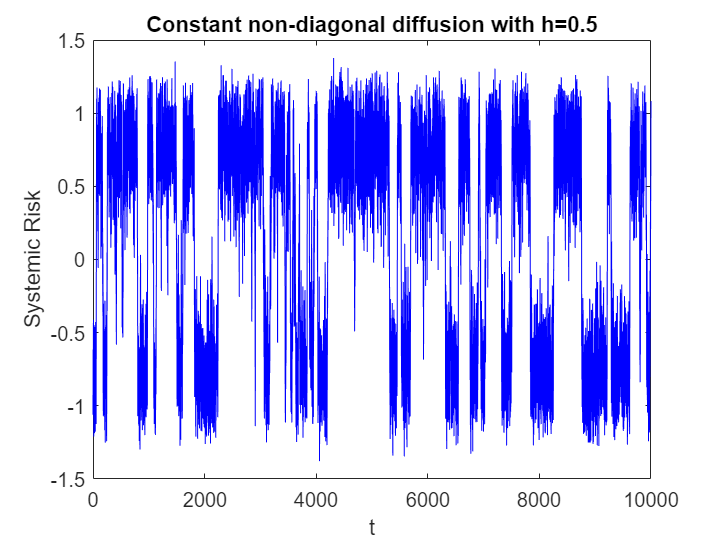

h = 0.5;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig.*(eye(N) + diag(0.5*ones(N-1, 1), 1) + diag(0.5*ones(N-1, 1), -1));    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant non-diagonal diffusion with h=0.5")

Now I try increasing h to 1

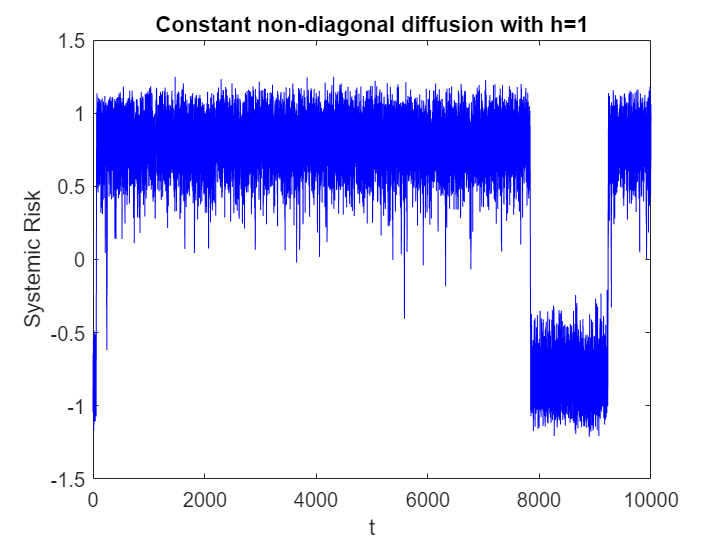

h = 1;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig.*(eye(N) + diag(0.5*ones(N-1, 1), 1) + diag(0.5*ones(N-1, 1), -1));    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant non-diagonal diffusion with h=1")

Bernchmark when h=1 and no correlated noise

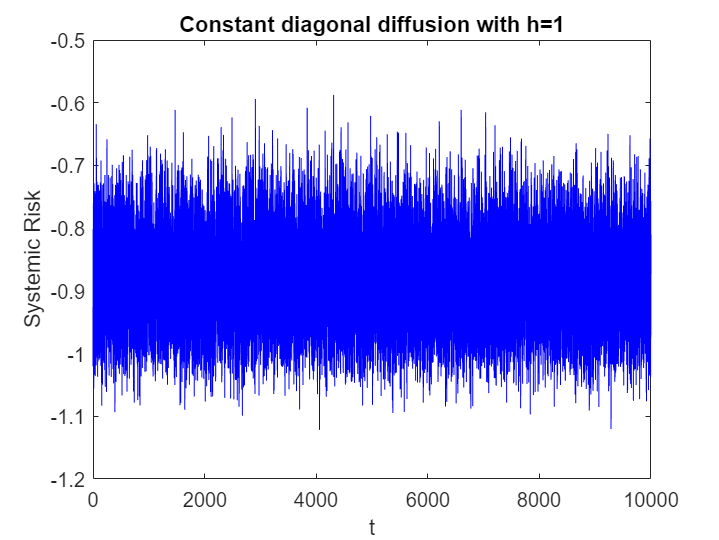

h = 1;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig;    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'yes');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant diagonal diffusion with h=1")

Here I simulated a denser correlation matrix. I use the correlation from an AR(1) process as an example.


$$\left(\begin{array}{ccccc}
1 & \rho & \rho^{2} & \cdots & \rho^{n-1} \\
\rho & 1 & \rho & \cdots & \rho^{n-2} \\
\vdots & \rho & \ddots & \ddots & \rho^{n-3} \\
\vdots & \vdots & \ddots & \ddots & \vdots \\
\rho^{n-1} & \rho^{n-2} & \rho^{n-3} & \cdots & 1
\end{array}\right)$$


Also h=1, so the intrinsic stabilising force is strong.

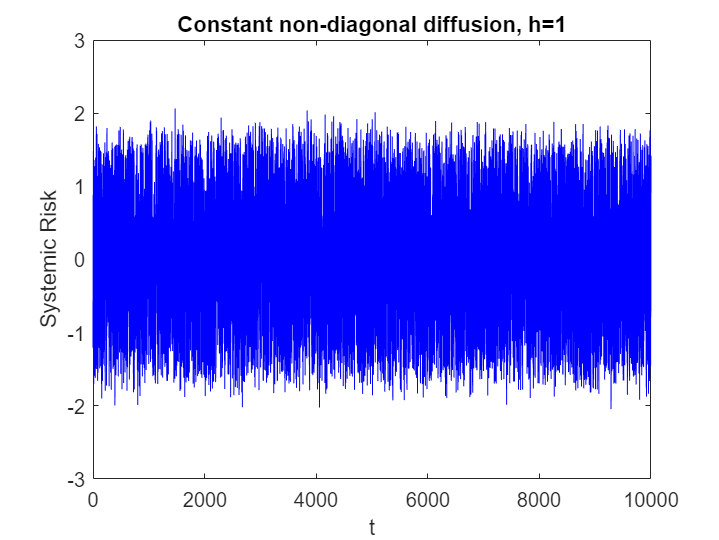

% Define SDE
h = 1;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
% AR(1) correlation matrix
g = @(t, x) sig.*ar1(N, 0.8);    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Constant non-diagonal diffusion, h=1")

The result is that the system is not stable at all...

I repeat the experiment of **removing weak banks** in the case of non-diagonal diffusion with h=1. Weak links can still lend.

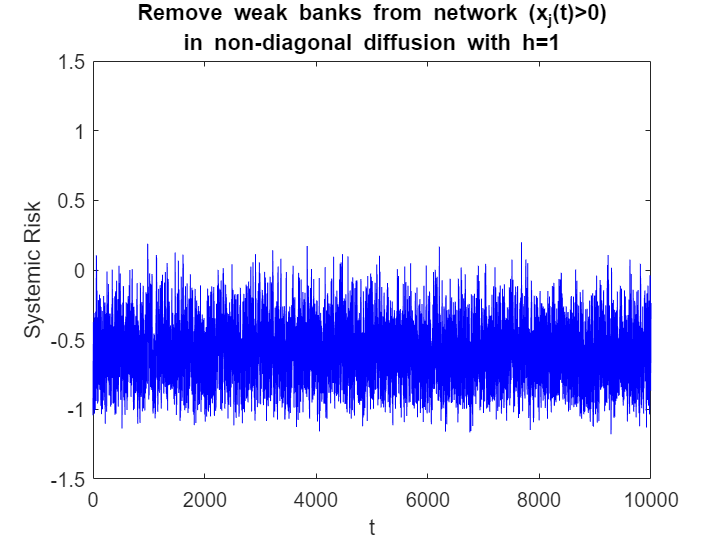

h = 1;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* RemoveWeakLink(x, 0); 
g = @(t, x) sig.*(eye(N) + diag(0.5*ones(N-1, 1), 1) + diag(0.5*ones(N-1, 1), -1)); 

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

PlotSDE(t, x);
ylim([-1.5, 1.5])
title(["Remove weak banks from network (x_{j}(t)>0)", ...
    "in non-diagonal diffusion with h=1"])

I repeat the experiment of **removing weak banks from borrowing** in the case of non-diagonal diffusion with h=1. Weak links can still lend.

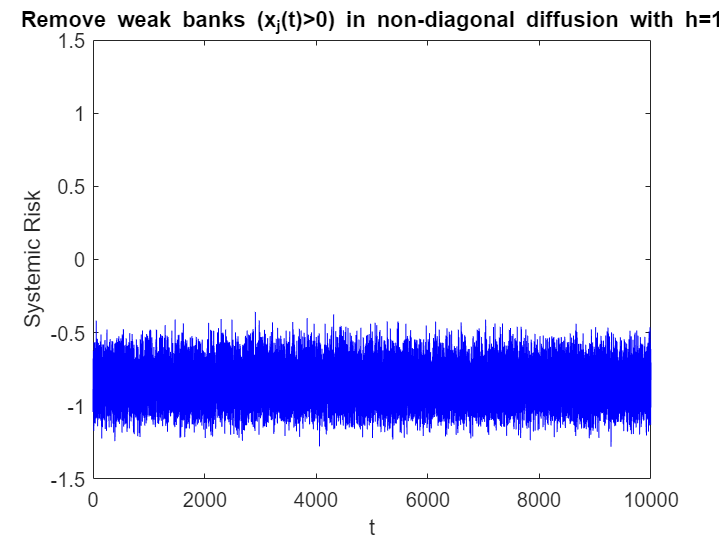

h = 1;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* RemoveWeakLink3(x, 0); 
g = @(t, x) sig.*(eye(N) + diag(0.5*ones(N-1, 1), 1) + diag(0.5*ones(N-1, 1), -1)); 

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

PlotSDE(t, x);
ylim([-1.5, 1.5])
title("Remove weak banks (x_{j}(t)>0) in non-diagonal diffusion with h=1")

Count how many above 0

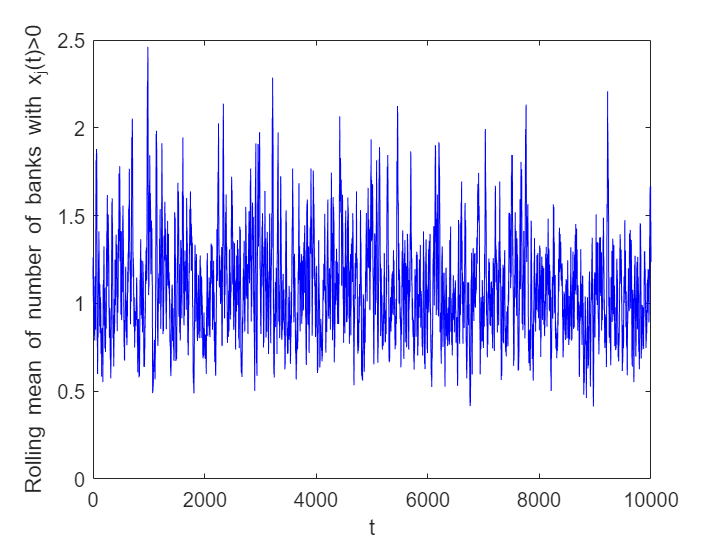

fail = sum(x > 0, 2);
plot(t, movmean(fail, 1000), 'b');
xlabel('t'); ylabel('Rolling mean of number of banks with x_{j}(t)>0');

**Carmona common noise**

The system is driven by N correlated standard Brownian motions:


$$\widetilde{W}_{t}^{i}=\rho W_{t}^{0}+\sqrt{1-\rho^{2}} W_{t}^{i}$$


The correlation matrix is therefore given by a (i, i+1) matrix:


$$\left(\begin{array}{ccccc}
\rho & \sqrt{1-\rho^2} & 0 & \cdots & 0 \\
\rho & 0 & \sqrt{1-\rho^2} & \cdots & 0 \\
\vdots & \vdots & 0 & \ddots & \vdots \\
\rho & 0 & 0 & \cdots &  \sqrt{1-\rho^2}
\end{array}\right)$$


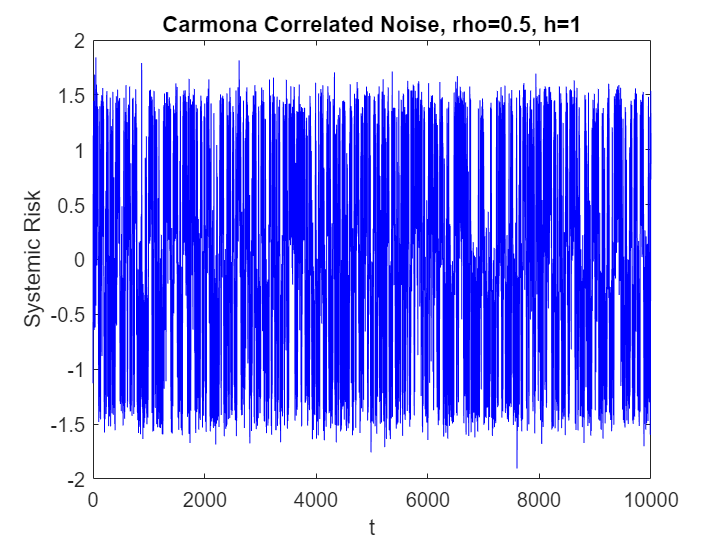

% Define SDE
h = 1;
x0 = -1 + zeros(N, 1);
U = @(y) y.^3 - y;
f = @(t, x) -h.*U(x) + theta.* (mean(x) - x); 
g = @(t, x) sig.*CarmonaNoise(N, 0.5);    

% Use Euler-Maruyama to solve SDE
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Carmona Correlated Noise, rho=0.5, h=1")

Carmona Noise without potential force

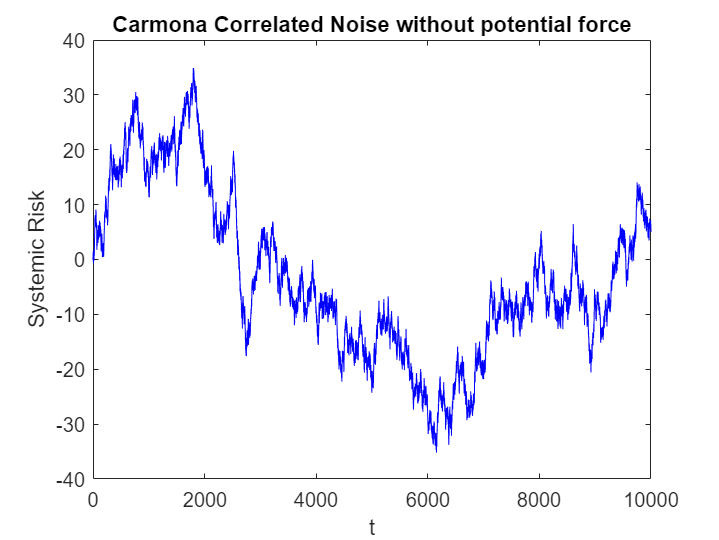

N = 10;
x0 = zeros(N, 1);
f = @(t, x) 10.* (mean(x) - x);
g = @(t, x) CarmonaNoise(N, 0.5);  
opts = sdeset('RandSeed', 1, 'Diagonal', 'no');
x = sde_euler(f, g, t, x0, opts); 

xbar = mean(x, 2);

figure; 
plot(t, xbar, 'b');
xlabel('t'); ylabel('Systemic Risk');
title("Carmona Correlated Noise without potential force")